clear
% Problem 1 

% Part (1)
% Z transform of difference equation 
syms y(n) z Ro
assume(n>=0 & in(n,"integer"))
virulence = 1.02; % Ro
f = y(n) - Ro*y(n-1) - kroneckerDelta(n);
fZT = ztrans(f,n,z);
syms yZT
fZT = subs(fZT,ztrans(y(n),n,z),yZT);
yZT = solve(fZT,yZT); 
yZT1 = subs(yZT,y(-1),0) % Transfer function H(z) = 1 / 1 - Ro*z^-1

$$yZT1 = -\frac{z}{\mathrm{Ro}-z}$$

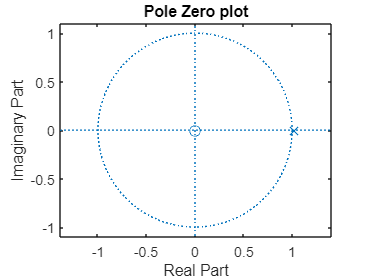

yZT = subs(yZT1,Ro,virulence); % Change Ro

[b,a] = numden(yZT);
num = sym2poly(b);
den = sym2poly(a);
zplane(num,den) % Pole Zero plot
title("Pole Zero plot")


% Part (2)
% Time domain Equation  
ySol = iztrans(yZT1,z,n); 
ySol = simplify(ySol) % Time domain equation y[n] = Ro^n u[n]

$$ySol = \left\{ \begin{array}{cl} \delta_{n,0} & \text{ if }\mathrm{Ro}=0\\ {\mathrm{Ro}}^{n} & \text{ if }\mathrm{Ro}\neq 0 \end{array}\right.$$

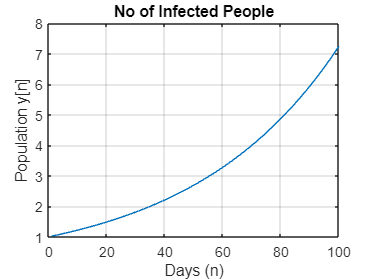

ySol = subs(ySol,Ro,virulence);
nValues = 1:100;
ySolValues = subs(ySol,n,nValues);
ySolValues = double(ySolValues);
ySolValues = real(ySolValues);
figure;
plot(nValues,ySolValues)
title("No of Infected People")
xlabel("Days (n)")
ylabel("Population y[n]")
grid on

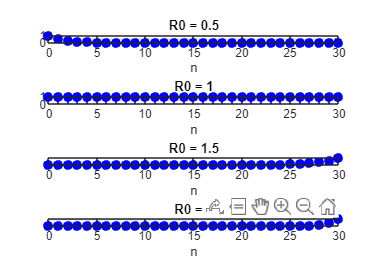


n = 0:30; % Define the range of n values
R0_values = [0.5, 1.0, 1.5, 2.0]; % Different R0 values to analyze

figure;

for i = 1:length(R0_values)
    R0 = R0_values(i);
    y = R0.^n .* (n >= 0); % Time-domain equation
    subplot(length(R0_values), 1, i);
    stem(n, y, 'b', 'filled');
    title(['R0 = ' num2str(R0)]);
    xlabel('n');
    ylabel('y[n]');
    grid on;
end



% Part (3)
% Days for 1 million infections
% y[n] = 10^6
% Ro = 2.5
% n = log(y[n]) / log(Ro) (Days) 
Days =floor(6/log10(2.5))

Days = 15


% Part (4)
% Covid first wave March - November 2020 (250 Days)
% Ro is estimated at an interval of 50 days in this period  
population = [5 18885 285979 1637079 5213755 8951323];
Ro = [0];
for i = population
    Ro(population == i) = 10^(log10(i)/50);
end
Ro_phase1 = mean(Ro) % Ro during first wave 

Ro_phase1 = 1.2679


% Part (5)
days = 0:20;
Ro = 2.5;
populationx = [0];
for i = days
    populationx(days == i) = Ro^i;
end
% Integrator filter
% H(z) = 1 / 1-z^-1
Integrator = filter(1,[1 -1],populationx);
Total_infections = Integrator(end) % Total infections in 20 days

Total_infections = 1.5158e+08

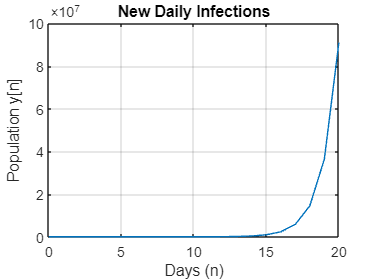


figure;
plot(days,populationx)
title("New Daily Infections")
xlabel("Days (n)")
ylabel("Population y[n]")
grid on

% Problem 2
% Transfer function
numerator = 1;
denominator = -1.*[-1, .1, .15, .25, .26, .34, .42, .25, .2, .15, .1, .1, .1];
ts = 0.1;
sys = tf(numerator,denominator,ts,'Variable','z^-1');

% Part (1)
H =1/( 1 - 0.1*z^-1 - 0.15*z^-2 - 0.25*z^-3 - 0.26*z^-4 - 0.34*z^-5 - 0.42*z^-6 - 0.25*z^-7 - 0.2*z^-8 - 0.15*z^-9 - 0.1*z^-10 - 0.1*z^-11 - 0.1*z^-12);
ySol1 = iztrans(H,z,n); % Time domain equation
ySol1 = simplify(ySol1); 
nValues1 = 1:100;
ySolValues1 = subs(ySol1,n,nValues1);

Error using sym/subs
Entries in second argument must be scalar.

ySolValues1 = double(ySolValues1);
ySolValues1 = real(ySolValues1);
figure;
plot(nValues1,ySolValues1)
title("New Daily Infections")
xlabel("Days (n)")
ylabel("Population y[n]")
grid on

Integrator1 = filter(1,[1 -1],ySolValues1);
Total_infections1 = Integrator1(end) % Total infections in 100 days

% Part(2)
Days = nValues1(ySolValues1 == ySolValues1(94))

% Problem 3
rho = [0.25 0.50 0.75];
for i = rho
    H_new =1/( 1 + (1-i)*(- 0.1*z^-1 - 0.15*z^-2 - 0.25*z^-3 - 0.26*z^-4 - 0.34*z^-5 - 0.42*z^-6 - 0.25*z^-7 - 0.2*z^-8 - 0.15*z^-9 - 0.1*z^-10 - 0.1*z^-11 - 0.1*z^-12));
    ySol2 = iztrans(H_new,z,n); % Time domain equation
    ySol2 = simplify(ySol2); 
    nValues2 = 1:100;
    ySolValues2 = subs(ySol2,n,nValues2);
    ySolValues2 = double(ySolValues2);
    ySolValues2 = real(ySolValues2);
    Integrator2 = filter(1,[1 -1],ySolValues2);
    Total_infections = Integrator2(end) % Total infections in 100 days
    figure;
    plot(nValues2,ySolValues2)
    title("New Daily Infections (rho = "+ i+")")
    xlabel("Days (n)")
    ylabel("Population y[n]")
    grid on
end

% Problem 4

% Part(1)
Ro = 1.15;
K = 10^6;
n = 1:100;

logistic = (K./(1+(K*(Ro-1) - Ro)*Ro.^(-n-1))) - (1/(Ro-1));
Integrator3 = filter(1,[1 -1],logistic);
Total_infections2 = Integrator3(end) % Total infections in 100 days

days = 0:100;
Ro = 1.15;
populationx = [0];
for i = days
    populationx(days == i) = Ro^i;
end
figure;
plot(n,logistic)
hold on 
plot(days,populationx)
hold off
title("New Daily Infections")
xlabel("Days (n)")
ylabel("Population y[n]")
grid on
legend("Logistic","First-order model")


% Part(2)
filter_1 = filter([1 -1],1,logistic); % First derivative
filter_2 = filter([1 -2 1],1,logistic); % Second derivative 

Global_maximum = max(filter_1) % Global max value
Value_n = n(filter_1 == max(filter_1)) % Days corresponding to max value
Zero_crossing = n(round(filter_2) == 94) % Inflection point

figure;
plot(n,filter_1,n(Value_n),filter_1(Value_n),'r*')
title("First derivative")
xlabel("Days (n)")
ylabel("Population y[n]")
grid on

figure;
plot(n,filter_2,n(Zero_crossing),filter_2(Zero_crossing),'r*')
title("Second derivative ")
xlabel("Days (n)")
ylabel("Population y[n]")
grid on
